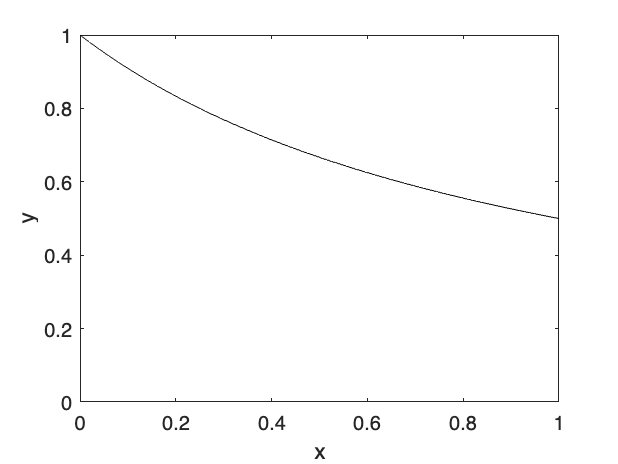

f = @(x) 1./(x+1);
x = linspace(0,1);
figure(1);
y = f(x);
plot(x,y,'k-')
xlabel x
ylabel y
axis([0 1 0 1]);


n = 10000;
for k = 1:5
    x = rand(n,1);
    y = rand(n,1);
    y0 = f(x);
    A0 = log(2);
    A1 = sum(y<y0)/n;
    A(k,1) = A1;
end
fprintf('The exact area is %.6f\n',A0)

The exact area is 0.693147


fprintf('For %d points, the estimated area is %.6f\n',n,mean(A))

For 10000 points, the estimated area is 0.691320


fprintf('The error is %.6f\n',abs((A0-A1)/A0))

The error is 0.007426
